# 清空现场

clear;
clc;

# 测试图像列表

testDir = '.\DecayRate';
picList = dir(testDir);
for i = size(picList,1):-1:1
    if picList(i).isdir
        picList(i) = [];
    end
end

# 统一测试参数

peakNum = 20;
diffData = [];
voteNum = zeros(2,size(picList,1));

# 逐个加载测试图片并分别测试SHT和DCHT算法

for i = 1:size(picList,1)
    thisPic = imread(strcat(picList(i).folder,'\',picList(i).name));
    thisGray = rgb2gray(thisPic);
    thisEdge = edge(thisGray,'canny');
    %% 标准Hough（SHT）
    [hSHT,thetaSHT,rhoSHT]=voteSHT(uint32(thisEdge));
    peaksSHT = houghpeaks(double(hSHT),peakNum,'Threshold',double(0.3*max(hSHT(:))));
    %% 采用方向编码的Hough（DCHT）
    [hDCHT,thetaDCHT,rhoDCHT]=voteDCHT(uint32(thisEdge));
    %% 统计
    if ~isempty(peaksSHT)
        diff = zeros(length(peaksSHT),1);
        voteNum(1,i) = sum(sum(hSHT));
        voteNum(2,i) = sum(sum(hDCHT));
        for j = 1:size(peaksSHT,1)
            v1 = double(hSHT(peaksSHT(j,1),peaksSHT(j,2)));
            v2 = double(hDCHT(peaksSHT(j,1),peaksSHT(j,2)));
            diff(j) = abs( v1-v2 )/v1;
            if diff(j)>0.05
                disp(picList(i).name);
            end
        end
    end
    diffData = [diffData;diff];
end

DecayR (12).bmp


DecayR (14).bmp


DecayR (17).bmp


# 分析

picNum = size(picList,1);
linesNum = length(diffData)

totalNum = 188

diffMean = mean(diffData)

diffMean = 0.0086

diffMax = max(diffData)

diffMax = 0.1030

diffStd = std(diffData)

diffStd = 0.0125

voteDecayRate = mean(abs(voteNum(1,:)-voteNum(2,:))/voteNum(1,:))

voteDecayRate = 0.5618

# 可视化

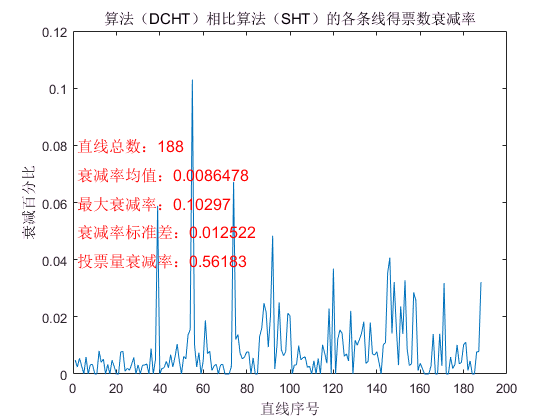

figure(1);
plot(diffData);
title('算法（DCHT）相比算法（SHT）的各条线得票数衰减率');
xlabel('直线序号');
ylabel('衰减百分比');
text(2,0.09,strcat('图片总数：',num2str(picNum)),'Color','red','FontSize',12);
text(2,0.08,strcat('直线总数：',num2str(linesNum)),'Color','red','FontSize',12);
text(2,0.07,strcat('衰减率均值：',num2str(diffMean)),'Color','red','FontSize',12);
text(2,0.06,strcat('最大衰减率：',num2str(diffMax)),'Color','red','FontSize',12);
text(2,0.05,strcat('衰减率标准差：',num2str(diffStd)),'Color','red','FontSize',12);
text(2,0.04,strcat('投票量衰减率：',num2str(voteDecayRate)),'Color','red','FontSize',12);